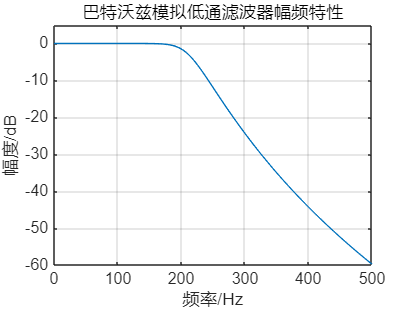

clc;clear;                % 清除命令窗口和工作区变量

% 设计滤波器参数
fp=200;                  % 通带截止频率为200Hz
fs=350;                  % 阻带截止频率为350Hz
dp=3;                    % 通带最大衰减为3dB
ds=35;                   % 阻带最小衰减为35dB

% 计算巴特沃兹滤波器阶数
[N,wp]=buttord(fp,fs,dp,ds,'s');    % 's'表示设计模拟滤波器

% 生成巴特沃兹滤波器系数
[B,A]=butter(N,wp,'s');             % B为分子系数，A为分母系数

% 计算频率响应
f=linspace(0,500,500);              % 生成0-500Hz的500个频率点
H=freqs(B,A,f);                     % 计算滤波器在这些频率点的响应

% 绘制幅频特性图
figure(1);
plot(f,20*log10(abs(H)));          % 将幅度转换为分贝(dB)形式并绘制
grid on;                           % 显示网格
axis([0 500 -60 5]);               % 设置坐标轴范围
xlabel('频率/Hz');                 % X轴标签
ylabel('幅度/dB');                 % Y轴标签
title('巴特沃兹模拟低通滤波器幅频特性');  % 图表标题